# Speech Emotion Recognition based on multi corpus

#                                                                -------- Re exp 2 part 2

## Adjustment

EMODB_use_num =100000;
RAVDESS_use_num = 20000;
SAVEE_use_num = 100000;

EMODB_ratio = EMODB_use_num/100000;
RAVDESS_ratio = RAVDESS_use_num/100000;
SAVEE_ratio = SAVEE_use_num/100000;

if (EMODB_ratio ~= 0) && (EMODB_ratio ~= 1)
    cvp = cvpartition(response_100000_EMODB, 'Holdout', EMODB_ratio);
    predictors_EMODB = predictors_100000_EMODB(cvp.test, :);
    response_EMODB = response_100000_EMODB(cvp.test, :);
else
    if (EMODB_ratio == 0)
        predictors_EMODB = [];
        response_EMODB =[];
    end
    if (EMODB_ratio == 1)
        predictors_EMODB = predictors_100000_EMODB;
        response_EMODB = response_100000_EMODB;        
    end
end

if (RAVDESS_ratio ~= 0) && (RAVDESS_ratio ~= 1)
    cvp = cvpartition(response_100000_RAVDESS, 'Holdout', RAVDESS_ratio);
    predictors_RAVDESS = predictors_100000_RAVDESS(cvp.test, :);
    response_RAVDESS = response_100000_RAVDESS(cvp.test, :);
else
    if (RAVDESS_ratio == 0)
        predictors_RAVDESS = [];
        response_RAVDESS =[];
    end
    if (RAVDESS_ratio == 1)
        predictors_RAVDESS = predictors_100000_RAVDESS;
        response_RAVDESS = response_100000_RAVDESS;        
    end
end  

if (SAVEE_ratio ~= 0) && (SAVEE_ratio ~= 1)
    cvp = cvpartition(response_100000_SAVEE, 'Holdout', SAVEE_ratio);
    predictors_SAVEE = predictors_100000_SAVEE(cvp.test, :);
    response_SAVEE = response_100000_SAVEE(cvp.test, :);
else
    if (SAVEE_ratio == 0)
        predictors_SAVEE = [];
        response_SAVEE =[];
    end
    if (SAVEE_ratio == 1)
        predictors_SAVEE = predictors_100000_SAVEE;
        response_SAVEE = response_100000_SAVEE;        
    end
end  

%-----------adjust--------that-------------------------
trained_EMODB = true;
trained_RAVDESS = true;
trained_SAVEE = true;

predictors_train = [];
response_train = [];

if trained_EMODB == 1
    predictors_train = [predictors_train;predictors_EMODB];
    response_train = [response_train;response_EMODB];
end
if trained_RAVDESS == 1
    predictors_train = [predictors_train;predictors_RAVDESS];
    response_train = [response_train;response_RAVDESS];
end
if trained_SAVEE == 1
    predictors_train = [predictors_train;predictors_SAVEE];
    response_train = [response_train;response_SAVEE];
end

### -----------------------------------------

### CHECK: this must be 100000

Train_num = height(predictors_train)

Train_num = 76721

### -----------------------------------------


%-----------adjust--------that-------------------------
tested_by = "RAVDESS";
switch tested_by
    case 'EMODB'
        validationPredictors = predictors_test_EMODB;
        validationResponse = response_test_EMODB;
    case 'RAVDESS'
        validationPredictors = predictors_test_RAVDESS;
        validationResponse = response_test_RAVDESS;
    case 'SAVEE'
        validationPredictors = predictors_test_SAVEE;
        validationResponse = response_test_SAVEE;
end


## Result

% Model part 
mdl = fitcknn(...
    predictors_train, ...
    response_train, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 5, ...
    'DistanceWeight', 'SquaredInverse', ...
    'Standardize', false, ...
    'ClassNames', categorical({'anger'; 'disgust'; 'fear'; 'happiness'; 'neutral'; 'sadness'}));

% Test part
[validationPredictions, validationScores] = predict(mdl, validationPredictors);
correctPredictions = (validationPredictions == validationResponse);
isMissing = ismissing(validationResponse);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);

% Draw the result
%{
figure(1);
confusion_matrix1 = confusionchart(validationResponse,validationPredictions);
confusion_matrix1.Title = {'';'stage 2 Re-exp 1';''};
confusion_matrix1.YLabel = 'True';
confusion_matrix1.XLabel = 'Prediction';
%}

- Confusion Matrix:

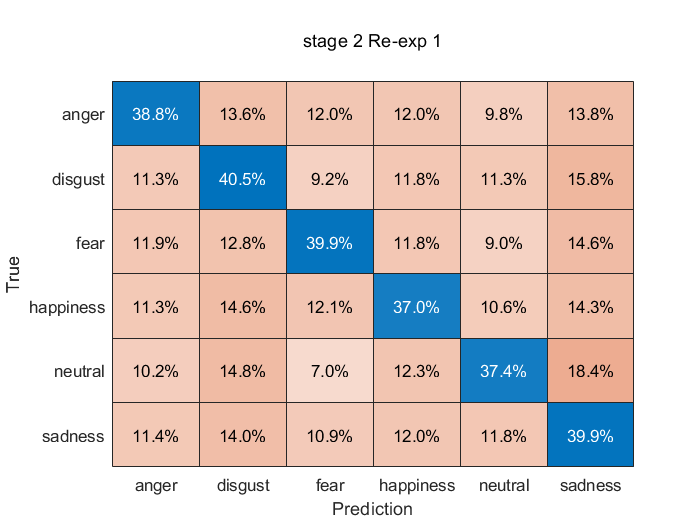

figure(2);
confusion_matrix2 = confusionchart(validationResponse,validationPredictions);
confusion_matrix2.Title = {'';'stage 2 Re-exp 1';''};
confusion_matrix2.YLabel = 'True';
confusion_matrix2.XLabel = 'Prediction';
% confusion_matrix2.RowSummary = 'row-normalized';
confusion_matrix2.Normalization = 'row-normalized';

- Average accuracy:

validationAccuracy

validationAccuracy = 0.3910

% Clear other vars:
clearvars -except response_100000_SAVEE ...
    predictors_100000_SAVEE ...
    response_100000_EMODB ...
    predictors_100000_EMODB ...
    response_100000_RAVDESS ...
    predictors_100000_RAVDESS ...
    response_test_SAVEE response_test_RAVDESS response_test_EMODB ...
    predictors_test_SAVEE predictors_test_RAVDESS predictors_test_EMODB;